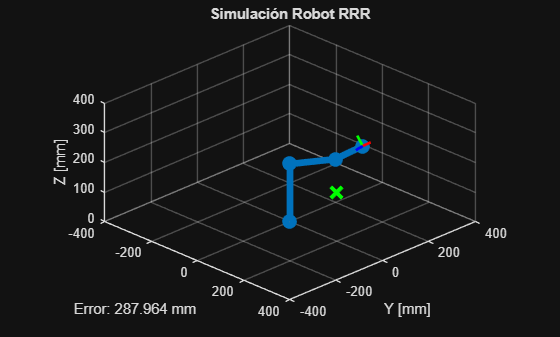

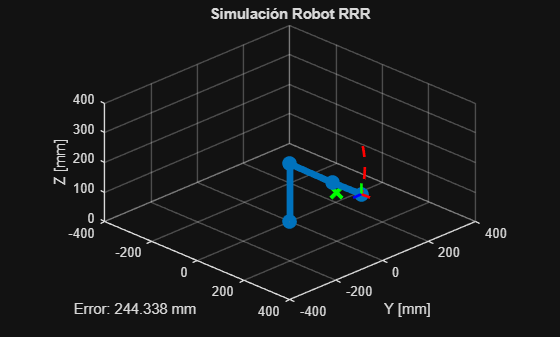

% TRAYECTORIAS
% Cinematica inversa
clc; clear; close all;
format short;

%% 1. PARÁMETROS DEL ROBOT (Longitudes en mm)
L1 = 195;  L2 = 180; L3 = 125;

% Parámetros DH base [theta, d, a, alpha]
DH_params = [
    0, L1, 0,  pi/2;  % Juntura 1
    0, 0,  L2, 0;     % Juntura 2
    0, 0,  L3, 0      % Juntura 3
];

%% 2. ENTRADA DE USUARIO Y CINEMÁTICA INVERSA
% fprintf('--- Cálculo de Cinemática Inversa ---\n');
% X = input('Ingrese X: ');
% Y = input('Ingrese Y: ');
% Z = input('Ingrese Z: ');

X=100;
Y=100;
Z=100;
P_obj = [X; Y; Z];

% Distancia radial y ángulo de base
r = sqrt(X^2 + Y^2);
theta1 = atan2(Y, X);

% Cálculo de ley de cosenos para Theta3
c3 = (X^2 + Y^2 + (Z-L1)^2 - L2^2 - L3^2) / (2*L2*L3);

if abs(c3) > 1
    error('El punto está fuera del espacio de trabajo.');
end

% Solución 1: CODO ARRIBA
theta3 = atan2(sqrt(1-c3^2), c3);
theta2 = atan2((Z-L1), r) - atan2(L3*sin(theta3), L2 + L3*cos(theta3));
q= [theta1; theta2; theta3];


%  CUADRATICA
clc;

tf = 5;
t = linspace(0, tf, 100);

v0 = 0;

% INICIALES 
q1_0 = deg2rad(10);
q2_0 = deg2rad(20);
q3_0 = deg2rad(15);

%FINALES 
q1_f = deg2rad(theta1);
q2_f = deg2rad(theta2);
q3_f = deg2rad(theta3);


a2_q1 = (q1_f - q1_0 - v0*tf)/(tf^2);
a2_q2 = (q2_f - q2_0 - v0*tf)/(tf^2);
a2_q3 = (q3_f - q3_0 - v0*tf)/(tf^2);

q1 = q1_0 + v0*t + a2_q1*t.^2;
q2 = q2_0 + v0*t + a2_q2*t.^2;
q3 = q3_0 + v0*t + a2_q3*t.^2;

%GRAFICA TRAYECTORIA
figure;
ax = axes;

for i = 1:length(t)

    q_actual = [q1(i); q2(i); q3(i)];

    P_deseado = P_obj; % puedes dejarlo fijo o hacerlo dinámico

    graficar_robot(ax, DH_params, q_actual, P_deseado, ...
        'Simulación Robot RRR', [0 0.447 0.741]);

    pause(0.05)
end

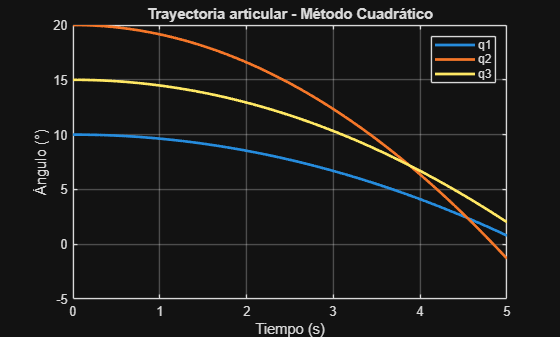


%% GRÁFICAS DE JUNTURAS
figure;
plot(t, rad2deg(q1),'LineWidth',2); hold on
plot(t, rad2deg(q2),'LineWidth',2);
plot(t, rad2deg(q3),'LineWidth',2);
grid on
legend('q1','q2','q3')
xlabel('Tiempo (s)')
ylabel('Ángulo (°)')
title('Trayectoria articular - Método Cuadrático')

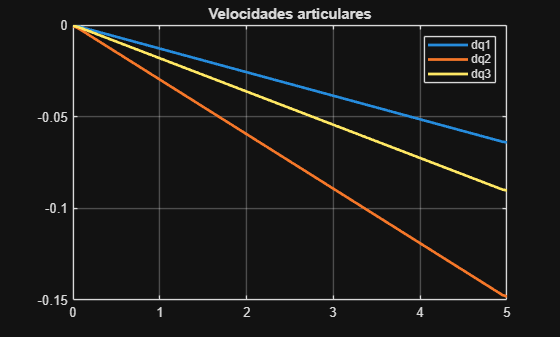


%% VELOCIDADES (para análisis)
dq1 = gradient(q1,t);
dq2 = gradient(q2,t);
dq3 = gradient(q3,t);

figure;
plot(t, dq1,'LineWidth',2); hold on
plot(t, dq2,'LineWidth',2);
plot(t, dq3,'LineWidth',2);
grid on
legend('dq1','dq2','dq3')
title('Velocidades articulares')

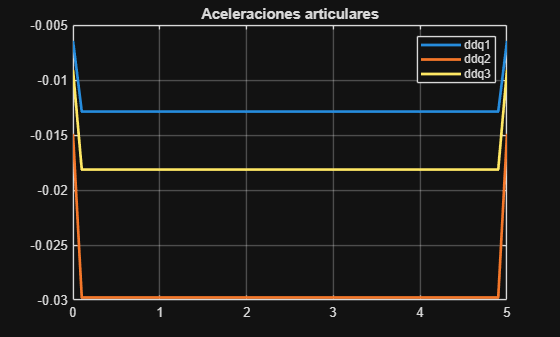


%% ACELERACIONES
ddq1 = gradient(dq1,t);
ddq2 = gradient(dq2,t);
ddq3 = gradient(dq3,t);

figure;
plot(t, ddq1,'LineWidth',2); hold on
plot(t, ddq2,'LineWidth',2);
plot(t, ddq3,'LineWidth',2);
grid on
legend('ddq1','ddq2','ddq3')
title('Aceleraciones articulares')



%Espacio junturas
%Funciones
%% 4. FUNCIONES AUXILIARES
function [O, T] = calcular_fk(DH, q)
    T = eye(4);
    O = zeros(size(DH,1)+1, 3);
    O(1,:) = [0 0 0];
    for j = 1:size(DH,1)
        th = DH(j,1) + q(j); d = DH(j,2); a = DH(j,3); al = DH(j,4);
        A = [ cos(th) -sin(th)*cos(al)  sin(th)*sin(al)  a*cos(th);
              sin(th)  cos(th)*cos(al) -cos(th)*sin(al)  a*sin(th);
              0        sin(al)           cos(al)          d;
              0        0                 0                1 ];
        T = T * A;
        O(j+1,:) = T(1:3,4).';
    end
end

function graficar_robot(ax, DH, q, P_obj, titulo, color_robot)

    % Trayectoria persistente
    persistent trayectoria
    
    if isempty(trayectoria)
        trayectoria = [];
    end

    % Cinemática directa
    [O, T_ee] = calcular_fk(DH, q);
    pEE = T_ee(1:3,4);

    % Guardar trayectoria
    trayectoria = [trayectoria; pEE'];

    % Limpiar eje
    cla(ax)
    hold(ax, 'on'); grid(ax, 'on'); axis(ax, 'equal');

    view(ax, 45, 25);
    xlabel(ax, 'X [mm]'); ylabel(ax, 'Y [mm]'); zlabel(ax, 'Z [mm]');
    title(ax, titulo);

    % Límites (ajustados a tu robot)
    limit = 400;
    axis(ax, [-limit limit -limit limit 0 limit]);

    % Punto objetivo
    plot3(ax, P_obj(1), P_obj(2), P_obj(3), ...
        'gx', 'MarkerSize', 12, 'LineWidth', 3);

    % Robot (eslabones)
    plot3(ax, O(:,1), O(:,2), O(:,3), ...
        '-o', 'LineWidth', 5, 'MarkerSize', 6, 'Color', color_robot);

    % Trayectoria del efector final
    plot3(ax, trayectoria(:,1), trayectoria(:,2), trayectoria(:,3), ...
        'r--', 'LineWidth', 2);

    %  Ejes del efector final
    R = T_ee(1:3,1:3);
    s = 40;
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,1)*s, R(2,1)*s, R(3,1)*s, 'r', 'LineWidth', 2);
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,2)*s, R(2,2)*s, R(3,2)*s, 'g', 'LineWidth', 2);
    quiver3(ax, pEE(1), pEE(2), pEE(3), R(1,3)*s, R(2,3)*s, R(3,3)*s, 'b', 'LineWidth', 2);

    % Error dinámico
    dist = norm(P_obj - pEE);
    xlabel(ax, sprintf('Error: %.3f mm', dist));

end

%Espacio de junturas
%% LÍMITE DE VELOCIDAD
qdot_max = 0.2; % rad/s

% Diferencias
dq1 = abs(q1_f - q1_0);
dq2 = abs(q2_f - q2_0);
dq3 = abs(q3_f - q3_0);

% Tiempo mínimo por cada articulación
tf1 = (2*dq1)/qdot_max;
tf2 = (2*dq2)/qdot_max;
tf3 = (2*dq3)/qdot_max;

% Tiempo final global (el más restrictivo)
tf = max([tf1 tf2 tf3]);

fprintf('Tiempo mínimo requerido: %.2f s\n', tf);

Tiempo mínimo requerido: 3.72 s


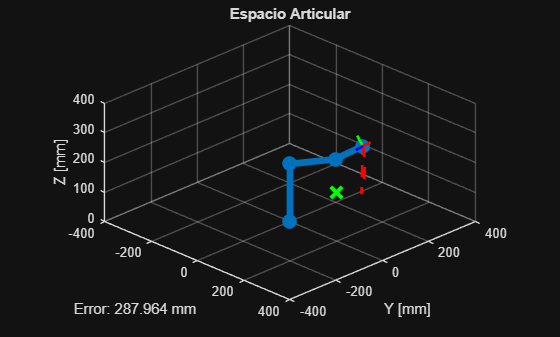

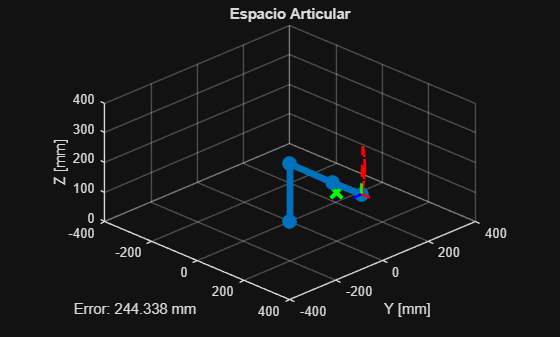


% Nuevo tiempo
t = linspace(0, tf, 100);
q1 = q1_0 + (q1_f - q1_0)/tf^2 * t.^2;
q2 = q2_0 + (q2_f - q2_0)/tf^2 * t.^2;
q3 = q3_0 + (q3_f - q3_0)/tf^2 * t.^2;

figure;
ax = axes;

for i = 1:length(t)

    q_actual = [q1(i); q2(i); q3(i)];

    % Punto objetivo (puede ser fijo)
    P_obj = [100;100;100];

    graficar_robot(ax, DH_params, q_actual, P_obj, ...
        'Espacio Articular', [0 0.447 0.741]);

    pause(0.05)
end